# Data generation and network training workflow

Generation if training data for a neural network that represents linear elastic isotropic material behaviour. Two neural networks are trained based on the generated data. One representing the normal stress response and the second one representing the shear stress response.

## Generate data

This part generates normal stress and trains the corresponding neural network

clear;close all;clc;

Set control flags

generate = 0; % data generation flag 0: load data  1: generate data
training = 0; % neural network training flag 0: load neural network training info  1: train neural network

Definition of input data

ndpoint = 200;
epslim1 = -0.01;
epslim2 = 0.01;

Material properties

E=68900; % Young's modulus
nu=0.33; % Poisson's ratio
lam = E/((1+nu)*(1-2*nu));

Allocate arrays for speed

dsize = ndpoint*ndpoint*ndpoint;
ndata = zeros(6,dsize);
sdata = zeros(2,ndpoint);

step = (epslim2-epslim1)/(ndpoint-1);


Generate data

if generate
    eps1=epslim1:step:epslim2;
    eps2=epslim1:step:epslim2;
    eps3=epslim1:step:epslim2;
    ndata(1:3,:) = combvec(eps1,eps2,eps3);
    sdata(1,:) = epslim1:step:epslim2;
    for i=1:size(ndata,2)
        ndata(4,i) = lam*(1-nu)*ndata(1,i) + lam*nu*ndata(2,i) + lam*nu*ndata(3,i);
        ndata(5,i) = lam*nu*ndata(1,i) + lam*(1-nu)*ndata(2,i) + lam*nu*ndata(3,i);
        ndata(6,i) = lam*nu*ndata(1,i) + lam*nu*ndata(2,i) + lam*(1-nu)*ndata(3,i);
    end
    disp('normal data generated');
    for i=1:ndpoint
        sdata(2,i) = lam*0.5*(1-2*nu)*sdata(1,i);
    end
    disp('Shear data generated');
    save('SEartificialData.mat','ndata','sdata');
  
else
    load('SEartificialData.mat');
end

Plot data

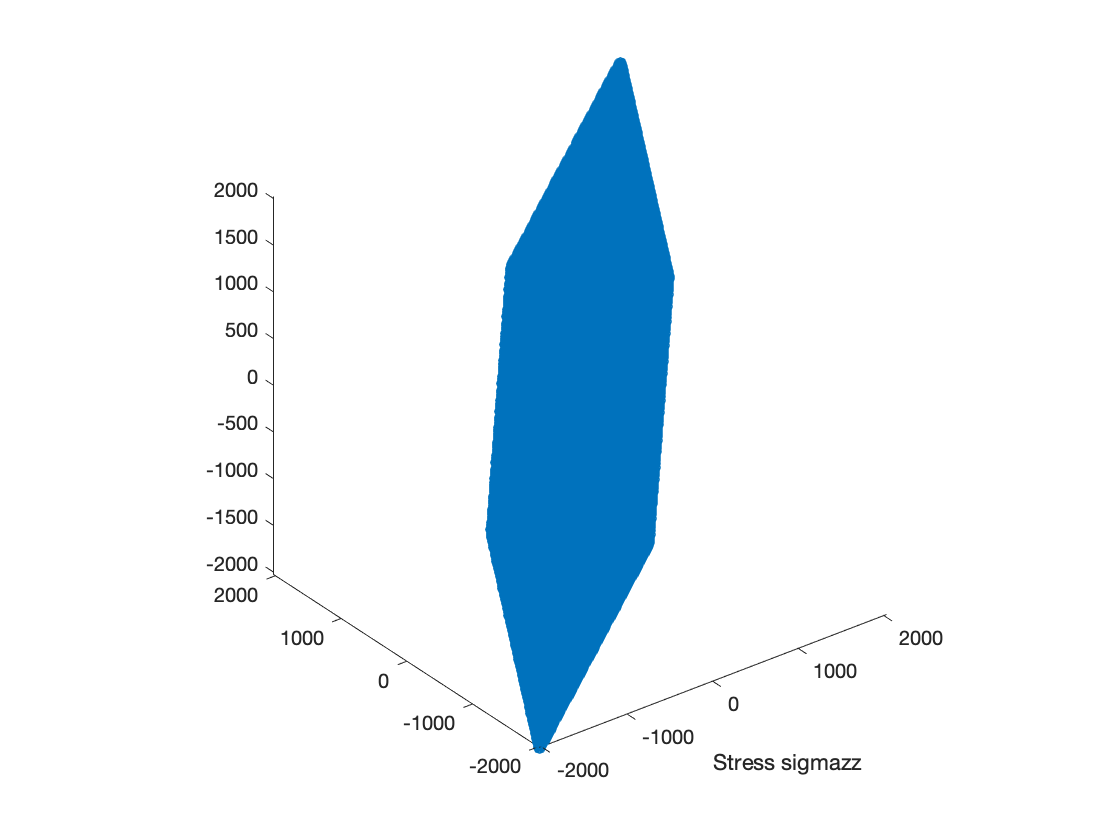

plot3(ndata(4,:),ndata(5,:),ndata(6,:),'o');
axis tight equal
xlabel('Stress sigmazz');
figure
plot(sdata(1,:),sdata(2,:));
title('Shear stress');

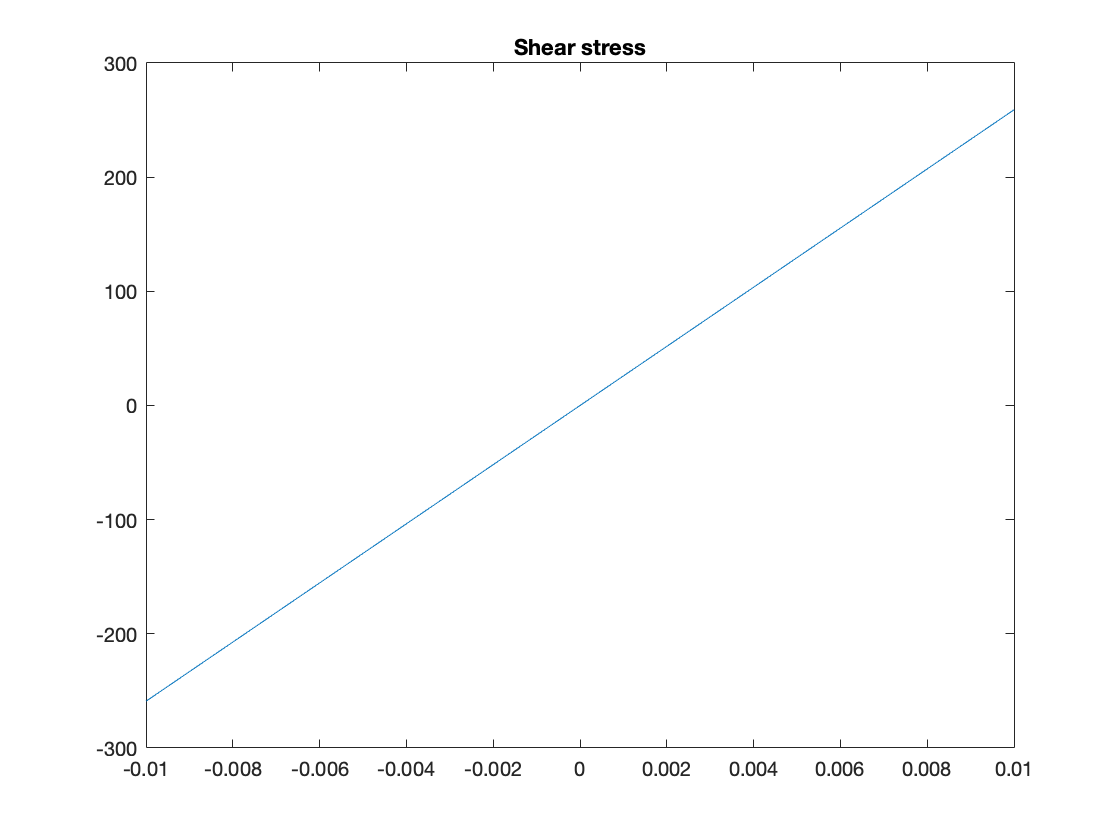

axis equal

## Train Neural network for normal stress

This section of the script can be very slow when training is performed on large data sets (many hours, days). Firstly, Matlab live scripts run much slower than standard m scripts (especially in Matlab versions older than 2019). Consider to convert the live script into an m file and then run it for large training sets. In addition, running it on a machine with multiple CPU's also speeds up the process. The Matlab neural network training tool supports parallel processing (this feature is also enables in this example).

Please note that a separate user interface will open during the network training. Training progress can be monitored through that UI. Training can be stopped when the performance plot (open by clicking on Performance button) does not show further improvement.

if training
    
    

Prepare input data

This network uses three input features (strain in x,y and z direction) and the corresponding 3 stresses (x,y and z) as labels.

1.Randomise order

    ssize = size(ndata,1);
    msize = size(ndata,2);
    k = randperm(msize);
    datared = ndata(:,k);
    input = datared(1:3,:);
    output = datared(4:6,:);

2.Normalise data

    inputreg =(max(abs(input')))';
    input = input./inputreg;
    outputreg = (max(abs(output')))';
    output =output./outputreg;


3.Create network (2 hidden layers with 10 units each)


    net1=feedforwardnet([10 10]);
    

4.Set training parameters

- trainFcn: optimisation algorithm to use (trainbr has demonstrated fastest convergence and highest accuracy for this dataset)

- epochs: number of iterations during training

- trainRatio: % of data to be used for training (default is 0.7)

- testRatio: % of data to be used for testing the network (default is 0.15)

- valRatio: % of data to be used for validating the network (default is 0.15)

- lr: Learning rate (default 0.001)

- processFcns: define what operations should be performed on the data before training, we alter the defaults as we do our own normalisation

This example uses Tansig activation functions for the hidden layers and a linear activation for the output layer. This is a typical setting for regression problems. The actiivation functions can be changed by setting net1.layers{i}.transferFcn to the required value. Please see Matlab documentation for details.

Note that the parameters discussed here are not complete. There are much more settings to control the network.

    % net.trainFcn = 'traingd'; % Gradient descent
    net1.trainFcn = 'trainbr'; % Bayesian regularisation (does not require validation data)
    % net.trainFcn = 'trainlm'; %  Levenberg-Marquardt optimization.
    % net.trainFcn = 'trainscg'; %  Scaled Conjugate Gradient.
    % switch of pre and post processing
    net1.trainParam.epochs = 500;
    % net.divideParam.trainRatio=0.7;
    % net.divideParam.testRatio=0.15;
    % net.divideParam.valRatio=0.15;
    % net.trainParam.lr=0.001;
    % net.trainParam.min_grad=1e-20;
    
    net1.inputs{1,1}.processFcns={'removeconstantrows'};
    net1.outputs{1,3}.processFcns={'removeconstantrows'};
    % net.trainParam;
 

5.Initialise training

    %     [net,tr] = train(net,input,output,'useParallel','yes','useGPU','yes');
    [net1,tr1] = train(net1,input,output,'useParallel','yes');

    save('trainedNN_normal.mat','input','inputreg','net1','output','outputreg','tr1');
else

    load('trainedNN_normal.mat');
end

6.Plot traing performance

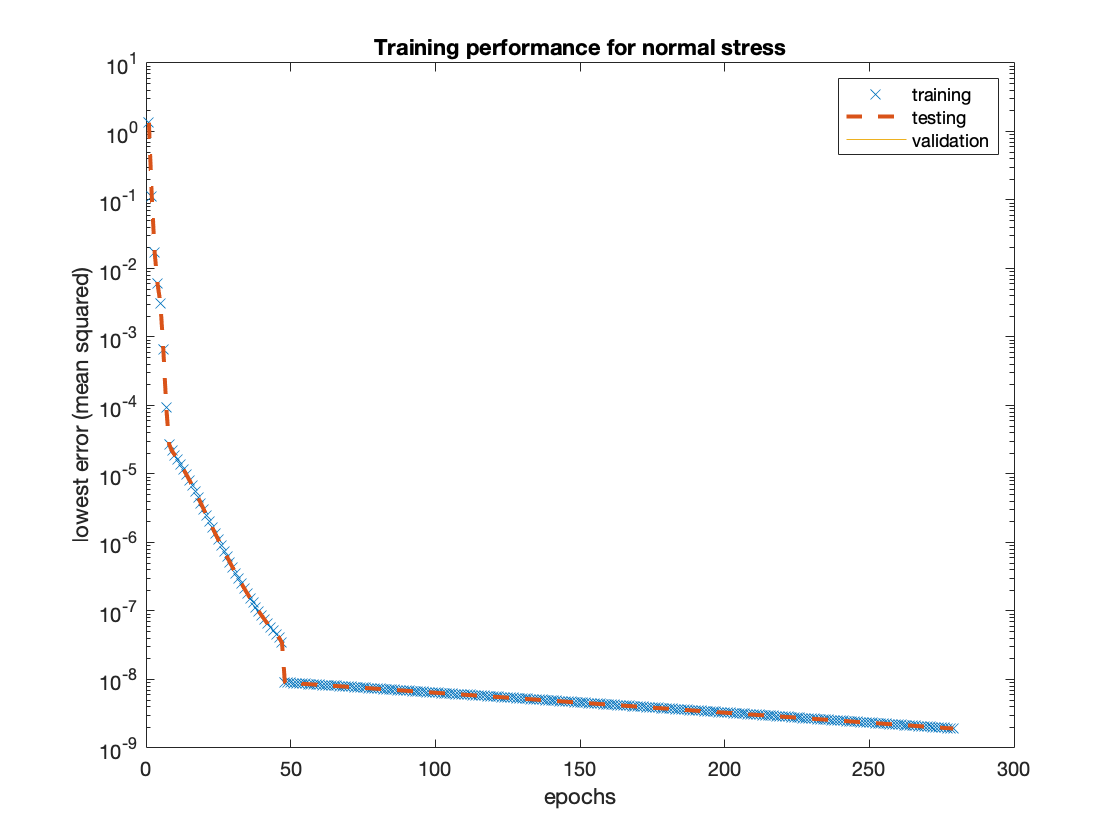

figure
plot(tr1.perf,'x');hold on;
plot(tr1.tperf,'--','linewidth',2);
plot(tr1.vperf);
legend('training','testing','validation');
set(gca,'YScale','log');
xlabel('epochs');
ylabel('lowest error (mean squared)');

title('Training performance for normal stress');

Plot error distribution

% evaluate performance

Array indices must be positive integers or logical values.

outerr = net1(input); % predict outputs from trained network
lasterr = output-outerr; % calculate difference of labels to predictions
figure
nob = 40; % number of bins in histogram
ploterrhist(lasterr,'bins',nob);
% set(gca,'YScale','log');
% set(gca,'XTickLabelRotation',90)
% xlabel('error (label - prediction)');
title('Error distribution (label - predictions)');

Extraction of trained weights and export to text file for integration in a fortran based constitutive model

% extract layers from network
layers=net1.layers;
% extract weights from layers
Iweights = net1.IW;
Lweights = net1.LW;
% extract bias for each layer
bias = net1.b;
weights{1}(:,1) = bias{1,1};
% extract weights of first hidden layer
weights{1}(:,2:size(Iweights{1,1},2)+1) = Iweights{1,1};
% extract weights of all subsequent layers
for i=2:size(layers,1)
    weights{i}(:,1) = bias{i,1};
    ns = size(Lweights{i,i-1},2);
    weights{i}(:,2:ns+1) = Lweights{i,i-1};
end    
% output weights in Fortran format
fid=fopen('weightsNormal.txt','w');
fprintf(fid,'c data normalisation\n');
for i=1:length(inputreg)
    fprintf(fid,['      Ninputreg(',num2str(i),') = %25.20f\n'],inputreg(i));
end
for i=1:length(outputreg)
    fprintf(fid,['      Noutputreg(',num2str(i),') = %25.20f\n'],outputreg(i));
end
fprintf(fid,'c weights of Neural Network\n');
for i=1:size(weights,2)
    for k=1:size(weights{1,i},1)
        for m=1:size(weights{1,i},2)
            fprintf(fid,['      Nweights(',num2str(i),',',num2str(k),',',num2str(m),') = %25.20f\n'],weights{1,i}(k,m));
        end
    end
end
fclose(fid);

clear weights Lweights bias Iweights datared;

## Train Neural network for shear stress

This section of the script can be  slow when training is performed on large data sets (but much faster than the one for normal stress). Firstly, Matlab live scripts run much slower than standard m scripts. Consider to convert the live script into an m file and then run it for large training sets. In addition, running it on a machine with multiple CPU's also speeds up the process. The Matlab neural network training tool supports parallel processing (this feature is also enables in this example).

Please note that a separate user interface will open during the network training. Training progress can be monitored through that UI. Training can be stopped when the performance plot (open by clicking on Performance button) does not show further improvement.

if training
    

Prepare input data

This network uses one input feature (one shear strain, for isotropic materials, the shear stiffness is the same for all shear components, hence training only one is sufficient) and the corresponding shear stresse as label.

1.Randomise order

    ssize = size(sdata,1);
    msize = size(sdata,2);
    k = randperm(msize);
    datared = sdata(:,k);
    input2 = datared(1,:);
    output2 = datared(2,:);

    

2.Normalise data

    inputreg2 =(max(abs(input2')))';
    input2 = input2./inputreg2;

    outputreg2 = (max(abs(output2')))';
    output2 =output2./outputreg2;


3.Create network (2 hidden layers with 10 units each)

    net2=feedforwardnet([10 10]);
    

4.Set training parameters

- trainFcn: optimisation algorithm to use (trainbr has demonstrated fastest convergence and highest accuracy for this dataset)

- epochs: number of iterations during training

- trainRatio: % of data to be used for training (default is 0.7)

- testRatio: % of data to be used for testing the network (default is 0.15)

- valRatio: % of data to be used for validating the network (default is 0.15)

- lr: Learning rate (default 0.001)

- processFcns: define what operations should be performed on the data before training, we alter the defaults as we do our own normalisation

This example uses Tansig activation functions for the hidden layers and a linear activation for the output layer. This is a typical setting for regression problems. The actiivation functions can be changed by setting net1.layers{i}.transferFcn to the required value. Please see Matlab documentation for details.

Note that the parameters discussed here are not complete. There are much more settings to control the network.

    % net.trainFcn = 'traingd'; % Gradient descent
    net2.trainFcn = 'trainbr'; % Bayesian regularisation
    % net.trainFcn = 'trainlm'; %  Levenberg-Marquardt optimization.
    % net.trainFcn = 'trainscg'; %  Scaled Conjugate Gradient.
    % switch of pre and post processing
    net2.trainParam.epochs = 500;
    % net.divideParam.trainRatio=0.7;
    % net.divideParam.testRatio=0.15;
    % net.divideParam.valRatio=0.15;
    % net.trainParam.lr=0.001;
    % net.trainParam.min_grad=1e-20;
    % net.trainParam.goal=1e-30;
    %     net = configure(net,input,output);
    net2.inputs{1,1}.processFcns={'removeconstantrows'};
    net2.outputs{1,3}.processFcns={'removeconstantrows'};
    % net.trainParam;
    

5.Initialise training

    %     [net,tr] = train(net,input,output,'useParallel','yes','useGPU','yes');

    [net2,tr2] = train(net2,input2,output2,'useParallel','yes');
    save('trainedNN_shear.mat','input2','inputreg2','net2','output2','outputreg2','tr2');
else
    load('trainedNN_shear.mat');
end

6.Plot traing performance

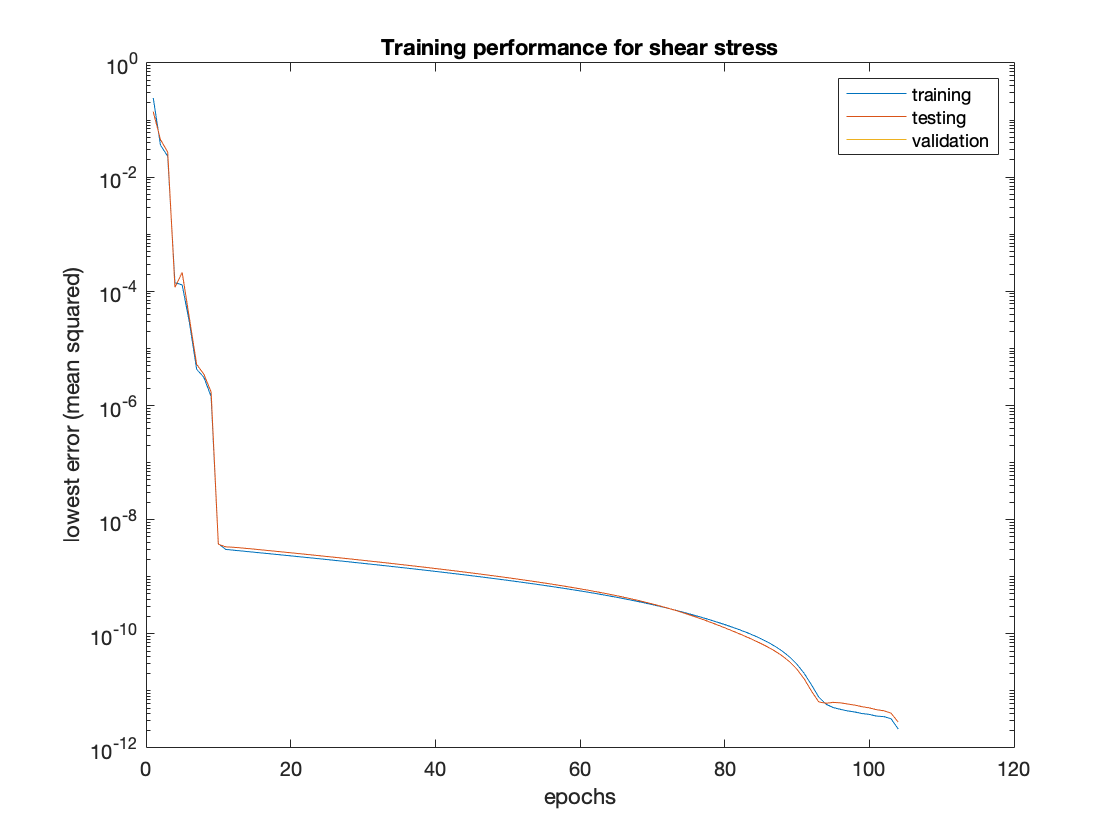

figure
plot(tr2.perf);hold on;
plot(tr2.tperf);
plot(tr2.vperf);
legend('training','testing','validation');

set(gca,'YScale','log');
xlabel('epochs');
ylabel('lowest error (mean squared)');

Array indices must be positive integers or logical values.

title('Training performance for shear stress');

Plot error distribution

% evaluate performance
outerr2 = net2(input2); % predict outputs from trained network
lasterr2 = output2-outerr2; % calculate difference of labels to predictions
figure
nob = 40; % number of bins in histogram
ploterrhist(lasterr2,'bins',nob);
% set(gca,'YScale','log');
% set(gca,'XTickLabelRotation',90)
% xlabel('error (label - prediction)');
title('Error distribution (label - predictions)');

Extraction of trained weights and export to text file for integration in a fortran based constitutive model

% get layers from network
layers=net2.layers; 
% extract weights
Iweights = net2.IW;
Lweights = net2.LW;
% extract bias
bias = net2.b;
% get weights from first hidden layer
weights{1}(:,1) = bias{1,1};
weights{1}(:,2:size(Iweights{1,1},2)+1) = Iweights{1,1};
% get weights of all layers that follow
for i=2:size(layers,1)
    weights{i}(:,1) = bias{i,1};
    ns = size(Lweights{i,i-1},2);
    weights{i}(:,2:ns+1) = Lweights{i,i-1};
end    
% output weights in Fortran format
fid=fopen('weightsShear.txt','w');
fprintf(fid,'c data normalisation\n');
for i=1:length(inputreg2)
    fprintf(fid,['      Sinputreg(',num2str(i),') = %25.20f\n'],inputreg2(i));
end
for i=1:length(outputreg2)
    fprintf(fid,['      Soutputreg(',num2str(i),') = %25.20f\n'],outputreg2(i));
end
fprintf(fid,'c weights of Neural Network\n');
for i=1:size(weights,2)
    for k=1:size(weights{1,i},1)
        for m=1:size(weights{1,i},2)
            fprintf(fid,['      Sweights(',num2str(i),',',num2str(k),',',num2str(m),') = %25.20f\n'],weights{1,i}(k,m));
        end
    end
end
fclose(fid);
clear datared;